# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 김강건**

**학번**** : 201910510**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : https://github.com/GangGeon10/DSP_homework**

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 


xn = [1,2,2,1];
N = 4;
Xk = dft(xn, N);
magXk =abs(Xk)

magXk =     6.0000    1.4142    0.0000    1.4142


phaXk = angle(Xk)*180 /pi

phaXk =          0 -135.0000  -90.0000  135.0000


xn = idft(Xk,N);
magxn = abs(xn)

magxn =      1     2     2     1



$$X\left(e^{\textrm{jw}} \right)=\sum_{n=0}^3 x\left(n\right)e^{-\textrm{jwn}} =1+{2e}^{-\textrm{jw}} +2e^{-\textrm{j2w}} +e^{-\textrm{j3w}}$$


2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.

xn = [1,2,2,1,0,0,0,0,0,0,0,0,0,0,0,0];
N = 16;
Xk = dft(xn, N);
magXk =abs(Xk)

magXk =     6.0000    5.5861    4.4609    2.9357    1.4142    0.2607    0.3170    0.3308    0.0000    0.3308    0.3170    0.2607    1.4142    2.9357    4.4609    5.5861


phaXk = angle(Xk)*180 /pi

phaXk =          0  -33.7500  -67.5000 -101.2500 -135.0000 -168.7500  -22.5000  -56.2500   90.0000   56.2500   22.5000  168.7500  135.0000  101.2500   67.5000   33.7500


xn = idft(Xk,N);
magxn = abs(xn)

magxn =     1.0000    2.0000    2.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$


$$\tilde{X} \left(k\right)=\sum_{n=0}^3 \tilde{x} \left(n\right){W_4 }^{\textrm{nk}} \;,\;k=0\;,\pm 1,\pm 2\ldotp \ldotp \ldotp$$



$$W_4 =e^{-j\frac{2\pi }{4}} =-j$$
 


$$\tilde{X} \left(0\right)=\sum_{n=0}^3 \tilde{x} \left(n\right){W_4 }^{n\;0} =\sum_{n=0}^3 \tilde{x} \left(n\right)=\tilde{x} \left(0\right)+\tilde{x} \left(1\right)+\tilde{x} \left(2\right)+\tilde{x} \left(3\right)=5$$



$$\tilde{X} \left(1\right)=\sum_{n=0}^3 \tilde{x} \left(n\right){W_4 }^{n\;} =\sum_{n=0}^3 \tilde{x} \left(n\right){\left(-j\right)}^n =5$$



$$\tilde{X} \left(2\right)=\sum_{n=0}^3 \tilde{x} \left(n\right){W_4 }^{2n\;} =\sum_{n=0}^3 \tilde{x} \left(n\right){\left(-j\right)}^{2n} =1$$



$$\tilde{X} \left(3\right)=\sum_{n=0}^3 \tilde{x} \left(n\right){W_4 }^{3n\;} =\sum_{n=0}^3 \tilde{x} \left(n\right){\left(-j\right)}^{3n} =5$$



xn = [4,1,-1,1];
N = 4;
Xk = dfs(xn,N)

Xk =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$


$$\tilde{X} \left(k\right)=\sum_{n=0}^4 \tilde{x} \left(n\right){W_5 }^{\textrm{nk}} \;,\;k=0\;,\pm 1,\pm 2\ldotp \ldotp \ldotp$$



$$W_5 =e^{-j\frac{2\pi }{5}}$$



$$\tilde{X} \left(0\right)=\sum_{n=0}^4 \tilde{x} \left(n\right){W_5 }^{n*0\;} =-1$$



$$\tilde{X} \left(1\right)=\sum_{n=0}^4 \tilde{x} \left(n\right){W_5 }^{n\;} =\;2\ldotp 618$$


$\tilde{X} \left(2\right)=\sum_{n=0}^4 \tilde{x} \left(n\right){W_5 }^{2n\;} =$ 0.382


$$\tilde{X} \left(3\right)=\sum_{n=0}^4 \tilde{x} \left(n\right){W_5 }^{3n\;} =0\ldotp 382$$



$$\tilde{X} \left(4\right)=\sum_{n=0}^4 \tilde{x} \left(n\right){W_5 }^{4n\;} =2\ldotp 618$$


xn = [1,0,-1,-1,0];
N = 5;
Xk = dfs(xn,N)

Xk =   -1.0000 + 0.0000i   2.6180 + 0.0000i   0.3820 - 0.0000i   0.3820 + 0.0000i   2.6180 + 0.0000i


3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\textrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \textrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 


n = [0:1:99];
x = sinc((n-50)/2) .^2;
y = x(1:1:100) ;
X = dft(y,100);
magX = abs(X);
phaX = angle(X) *180 /pi;
subplot(3,2,1);
stem(n, magX);
subplot(3,2,2);
stem(n,phaX);

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

subplot(3,2,3);
plot(n, magX);
subplot(3,2,4);
plot(n, phaX)

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.


subplot(3,2,5); hold on;
stem(n, magX);
plot(n, magX);

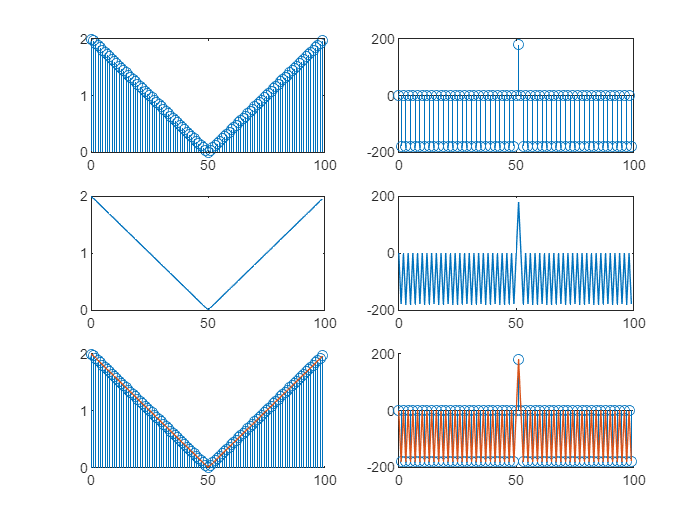


subplot(3,2,6); hold on;
stem(n,phaX);
plot(n, phaX);

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

$X\left(e^{\textrm{jw}} \right)=\frac{1-e^{-\textrm{jwN}} }{N}\sum_{k=0}^{N-1} \frac{\tilde{X} \left(k\right)}{1-e^{\textrm{j2}\pi \frac{k}{N}} e^{-\textrm{jw}} }=\sum_{k=0}^{N-1} \tilde{X} \left(k\right)\frac{1-e^{-\textrm{jwN}} }{N\left\lbrace 1-e^{\textrm{j2}\pi \frac{k}{N}} e^{-\textrm{jw}} \right\rbrace }=\sum_{k=0}^{N-1} \tilde{X} \left(k\right)\Phi \left(w-2\pi \frac{k}{N}\right)$                                                       $\Phi \left(w\right)=\frac{\sin \left(\frac{\textrm{wN}}{2}\right)}{\textrm{Nsin}\left(\frac{w}{2}\right)}e^{-\textrm{jw}\left(\frac{N-1}{2}\right)}$   : 보간 다항식

function [Xk] = dft(xn,N)

n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn * WNnk;


end


function [xn] = idft(Xk,N)


n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^(-nk);
xn = (Xk *WNnk) /N;


end


function [Xk] = dfs(xn,N)

n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn * WNnk;

end




